Copyright © 2021  Shababuddin Khan  || sk@pcampus.edu.np

*Department of Electrical Engineering, *[Pulchowk Campus](https://pcampus.edu.np/)*, Tribhuwan University, Nepal*

A Series of  Module has been designed and developed by author mentioned above with full copyright for a course of **Control System** to demonstrante the concept of control system and its implementation in real life to second year Aerospace engineering students at Tribhuwan University.

# ***MODULE VII: Frequency Response***

Frequency response is coined to the examination of the response of a system in steady state to an input to a sinusoidal signal. Bode, Nyquist, Polar Plots are used for frequency domain visulaization.

# ***7.1 Frequency Domain Characterization of the system***

%Defining the system
syms s w
sys=1000/(s*(1+0.1*s)*(1+0.001*s));
sys_w=subs(sys,s,1j*w)

$$sys\_w = -\frac{1000\,\mathrm{i}}{w\,\left(1+\frac{w\,\mathrm{i}}{10}\right)\,\left(1+\frac{w\,\mathrm{i}}{1000}\right)}$$

Magnitude=abs(sys_w)

$$Magnitude = \frac{1000}{\left|1+\frac{w\,\mathrm{i}}{10}\right|\,\left|1+\frac{w\,\mathrm{i}}{1000}\right|\,\left|w\right|}$$

Phase=angle(sys_w)

$$Phase = \text{angle}\left(-\frac{\mathrm{i}}{w\,\left(1+\frac{w\,\mathrm{i}}{10}\right)\,\left(1+\frac{w\,\mathrm{i}}{1000}\right)}\right)$$

# ***7.2 Sinusoidal Response***

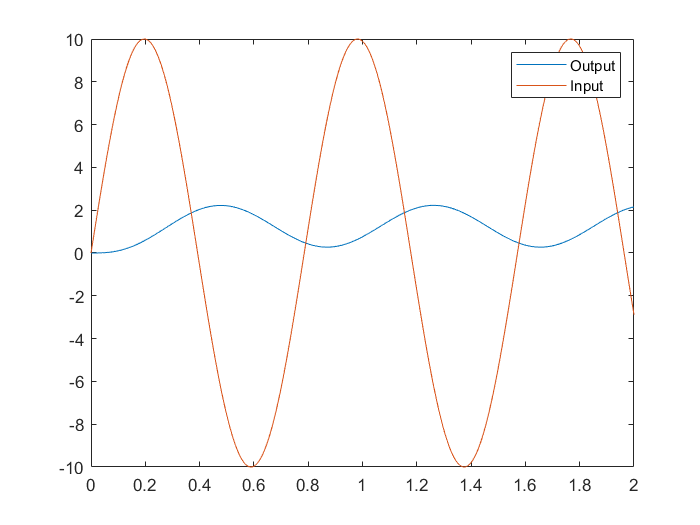

s=tf('s');
sys=10/(s*(s+10));                                   % Define LTI System
t = 0:0.001:2;                                       % Time Vector
u = 10*sin(8*t);                                     % Forcing Function
y = lsim(sys, u, t);                                 % Calculate System Response
figure
plot(t, y)
hold on
plot(t,u);
legend Output Input
hold off

# ***7.3 Bode Plot***

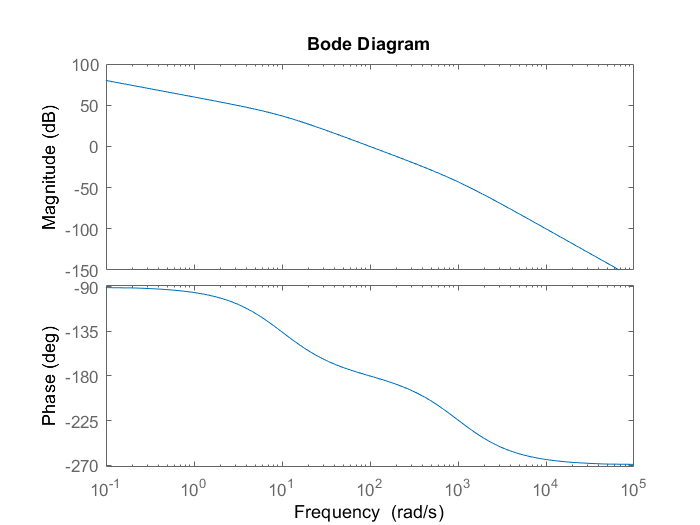

%define the system
s=tf('s');
G1=1000/(s*(1+0.1*s)*(1+0.001*s));  % Define system in s-domian
% Plot Bode using bode command
bode(G1)

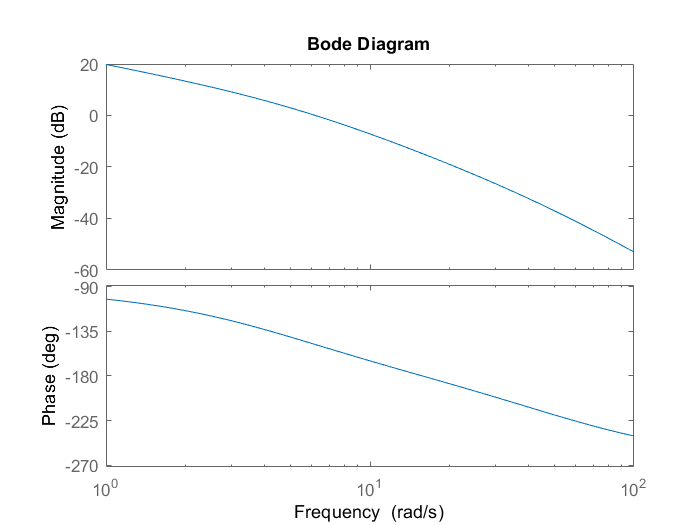

%-----------------------------------------------------------
% Some Other Examples
%-----------------------------------------------------------
 G=10/(s*(1+0.2*s)*(1+0.02*s));
 %bode(G)
 % To plot bode within certain frequency range 
 bode(G,{1,100})

%  G2=512*(s+3)/(s*(s^2+16*s+256));
%  bode(G2)
% G3=(4*s+40)/((s^2+4*s+25)*(s^2+50*s));
% bode(G3)
% G4= 250/(s*(s+50)*(s+5));
% bode(G4)
%  G5=(20*s+200)/((s^2+4*s+25)*(s^2+40*s));
%  bode(G5)

# ***7.4 Perfomance Specifications***

%define the system
s=tf('s');
G=1000/(s*(1+0.1*s)*(1+0.001*s));  % Define system in s-domian
% Plot Bode using bode command
bode(G)

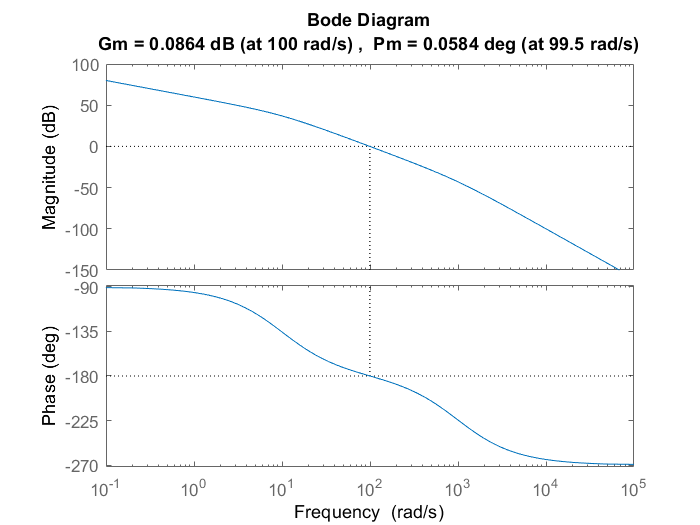

% Visual display of G.M., P.M. , G.C.F AND P.C.F.
margin(G)

% Getting the numeric Value of G.M., P.M. , G.C.F AND P.C.F.
[gm, pm, wcp, wcg]= margin(G)          % Magnitute in absolute units.

gm = 1.0100

pm = 0.0584

wcp = 100.0000

wcg = 99.4863

# ***7.5 Asymptotic Bode Plot***

%define the system
s=tf('s');
G=(4*s+40)/((s^2+5*s+20)*(s^2+50*s))


G =
 
             4 s + 40
  -------------------------------
  s^4 + 55 s^3 + 270 s^2 + 1000 s
 
Continuous-time transfer function.



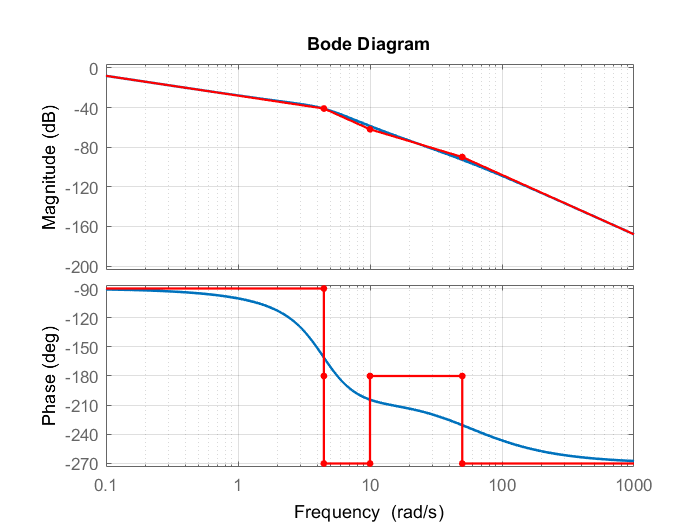

%G=1000/(s*(1+0.1*s)*(1+0.001*s));  % Define system in s-domian
% Plot Asymptotic Bode
asymp_bode(G);

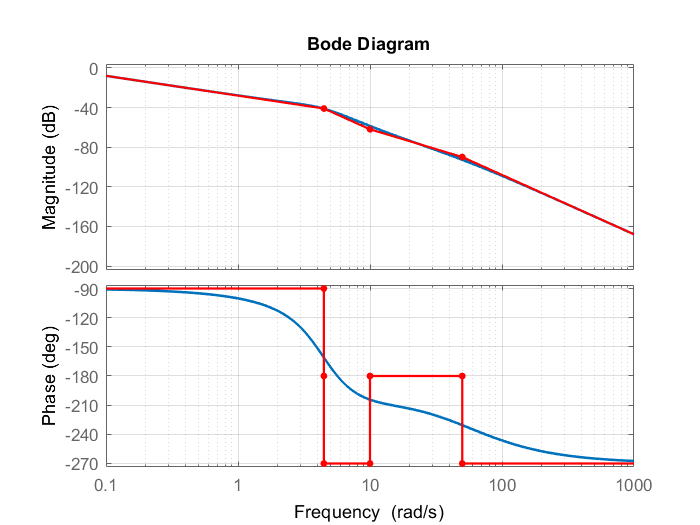

asymp_bode(G,0.1,1000);

%define the system
s=tf('s');
G=(4*s+40)/((s^2+5*s+20)*(s^2+50*s))


G =
 
             4 s + 40
  -------------------------------
  s^4 + 55 s^3 + 270 s^2 + 1000 s
 
Continuous-time transfer function.



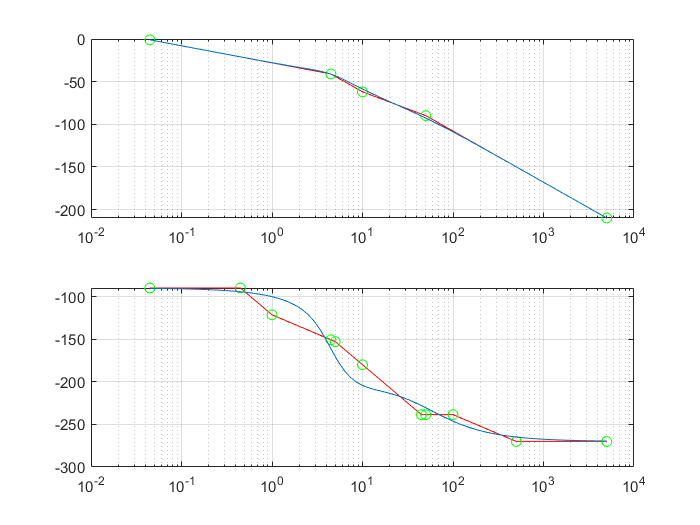


ii =

  0×1 empty double column vector


jj =

  0×1 empty double column vector



%G=1000/(s*(1+0.1*s)*(1+0.001*s));  % Define system in s-domian
% Plot Asymptotic Bode
asymp_bode_1(G);

# ***7.6 Effect of Gain and Time Constant on Bode Plot***

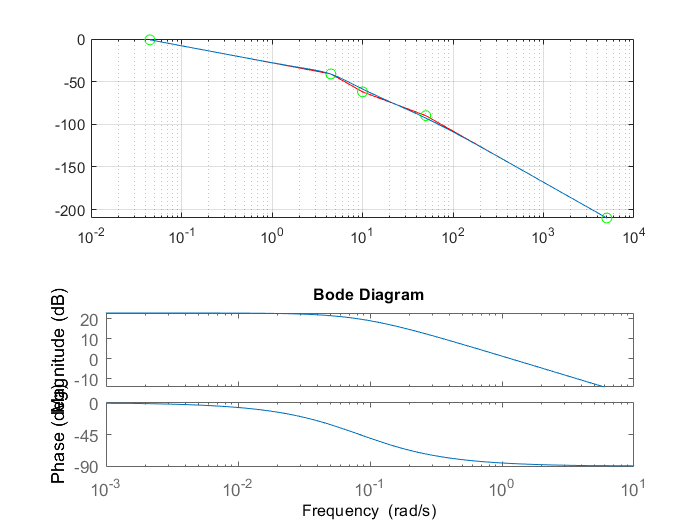

%define the system
s=tf('s');
K=14; % Chnage only in magnitute plot[Increase in Value]
T=12; % Change only in Phase [Cauding a time delay]
G=K/(1+T*s);
bode(G);
hold on

# ***7.7 Polar Plot***

hold off

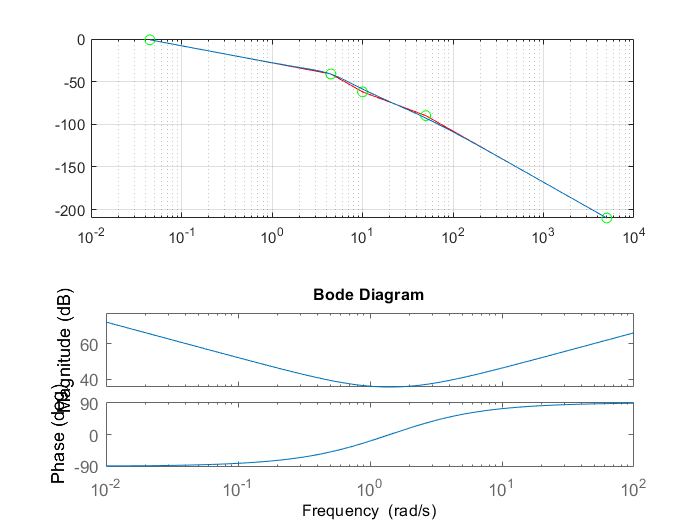

s=tf('s');
G=20/s*(1+s)*(s+2);
bode(G);

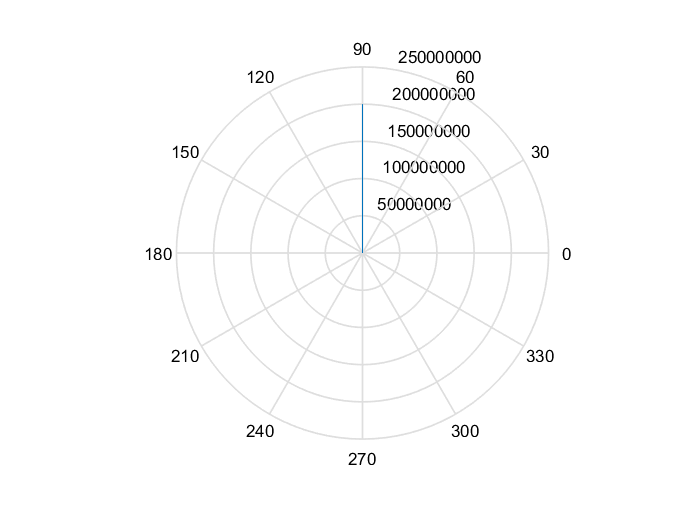

w=logspace(-3,7,1000000);
[mag,phase]=bode(G,w);          % Obtaining Magnitute and Phase at w
phase=phase(1,:);
mag=mag(1,:);
figure;
polar(phase*pi/180,mag);

# ***7.8 Nyquist  Plot***

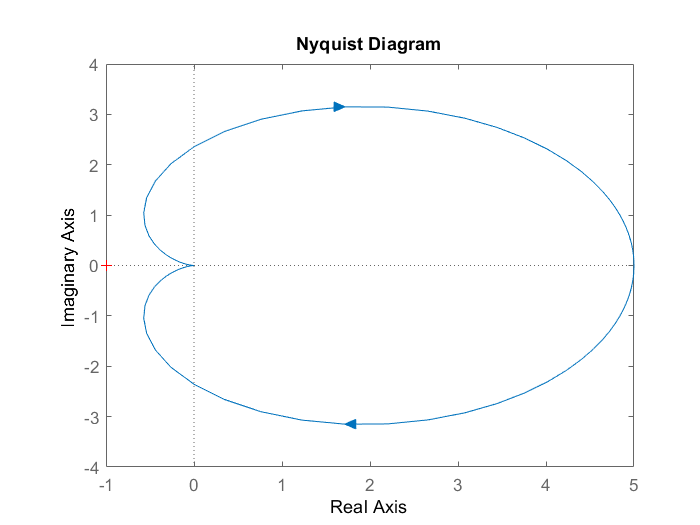

s=tf('s');
G=90/((s+3)*(s+6));
nyquist(G)

# References

- Mathworks.inc

- Nise, Norman S. "Control system engineering, John Wiley & Sons." *Inc, New York*(2011).

- [https://ctms.engin.umich.edu/CTMS/index.php?aux=Home](https://ctms.engin.umich.edu/CTMS/index.php?aux=Home)

- Bakshi, Uday A., and Varsha U. Bakshi. *Control system engineering*. Technical Publications, 2020.